**Below we recover the interaction force and diffusivity from a 1D attractive-repulsive swarm. Change "select_example" to 1,2, or 3 to recover from purely extrinsic noise, constant-diffusivity intrinsic noise, or variable-diffusivity intrinsic noise. **

## Load particle data

addpath(genpath('../'))
set(0,'DefaultFigurePosition',[1200 800 580 406])
warning('off','MATLAB:dispatcher:UnresolvedFunctionHandle')
clear;close all;clc;

select_example = 3;
examples = {'extrinsic_noise','constant_intrinsic_noise','varible_intrinsic_noise'};

if isequal(examples{select_example},'extrinsic_noise')
    load('datasets/qanr1D_N2000_nu0.mat'); 
    extrinsic_nz = 10^(-1.5);
elseif isequal(examples{select_example},'constant_intrinsic_noise')
    load('datasets/qanr1D_N2000.mat'); 
    extrinsic_nz = 0;
elseif isequal(examples{select_example},'varible_intrinsic_noise')
    load('datasets/qanr1D_N2000_sigx.mat'); 
    extrinsic_nz = 0;
end

## Compute approximate particle distribution $U$ from particles Xscell

%%% choose experiments from Xscell to use in regression 
exps = 1:4;

%%% choose number of particles to use from each experiment
NN = size(Xscell{1},1);

%%% choose histogram grid resolution
numx = 256 + 1;
numsdv = 3;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0 1 1]];
scoord = 0;

%%% set extrinsic noise level
Xsnz = [extrinsic_nz 1];

%%% compute histogram
get_particle_distrib;

ET_load_data = 0.0515 


plotgap=1;
plot_distrib;

## Choose model library

%%% local autonomous operators
max_dx = 0;
max_dt = 0;
polys = [];
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {@(mat,lhs) find(all([mat(:,2)==0 mat(:,3)==0 ~ismember(mat,lhs,'rows')],2))};
toggle_comb = 1;

%%% local non-autonomous operators
driftpolys=[0 2:8]; drifttrigs=[];
diffpolys=[0:8]; difftrigs=[]; crossdrift=1;

%%% non-local operators
dim = size(Xscell{1},2)+1;
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[0:6],'Sing',[],'Exp',[],'Singeps',[0.01],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 0.0773 


## Set weak discretization

phi_class = {1,1};
sm_x = 5;
sm_t = 5;

%%% manually set test function params
p_x = 5; mxs = 29;
tau_x = []; k_x = []; tauhat_x = []; 
p_t = 3; mts = 8;
tau_t = []; k_t = []; tauhat_t = [];

%%% set test function params using cornerpoint
% tauhat_x = 3; tau_x = 10^-4;
% p_x = []; mxs = 1;
% tauhat_t = 1; tau_t = 10^-4;
% p_t = []; mts = 1;

%%% rescale coordinates and/or use approx. variance for improved conditioning
scales = 2;
covtol = 0; 

%%% trim rows with low particle density
trim_tags = [1 zeros(1,dim-1) 0]; 
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-2;

set_discretization;

ET_setdisc = 0.4024 


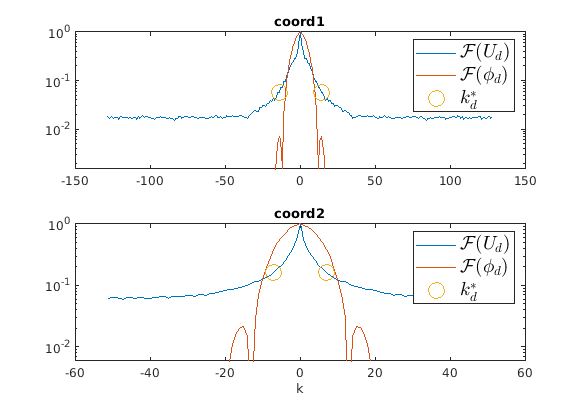


toggle_plot_fft = 1;
plot_Ufft;

## Build linear system

build_Gb;

ET_build_Gb = 0.0490 


## Solve linear system

lambda = 10.^(linspace(-4, 0, 50));
gamma_tol = Inf;
alpha = 0.5;
maxits = Inf;
sparsity_scale = 0;
excl_tags= {'u^{1}_{lap}','u^{1}_{xx}','([x.^0.*t.^0]u^1)_{xx}','([x.^0.*y.^0.*t.^0]u^1)_{lap}'};
excl_tols=0;
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 0.5705 


## get_results

print_loc = 1;
get_results;


Recovered PDE: u^{1}_{t} = 0.369052([x.^0.*t.^0]u^1)_{xx} + -0.375232([x.^1.*t.^0]u^1)_{xx} + 0.095772([x.^2.*t.^0]u^1)_{xx} + -1.01726convmonx0 + 1.01015convmonx1
Relative Res: ||b-G*W||_2/||b||_2 = 9.45e-02
Max Weight Error: max|W-W_{true}| = 3.09e-02
TP Score = 1.00
      
polys = 1 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 29 8 
[s_x s_t] = 5 1 
[p_x p_t] = 5 3 
 scales = 1.00e+00 4.01e+00 6.25e+00 
      
Total particles = 8000 
Size of dataset = 256 101 
Size G = 3355 24 
Cond G = 2.68e+07
[lambda_hat gamma] = 3.393e-02 0.000e+00 
[sigma_NR sigma] = 0.000e+00 
      
STLS its = 4 
 
ET_load_data = 0.0515 
ET_build_lib = 0.0773 
ET_setdisc = 0.4024 
ET_build_Gb = 0.0490 
ET_solve_sparse_reg = 0.5705 
Elapsed time WSINDy = 1.1507 


## Display loss

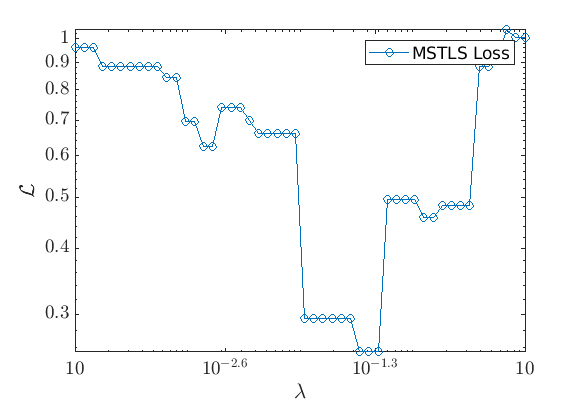

toggle_plot_loss = 1;
plot_loss;

## Display drift/diffusion

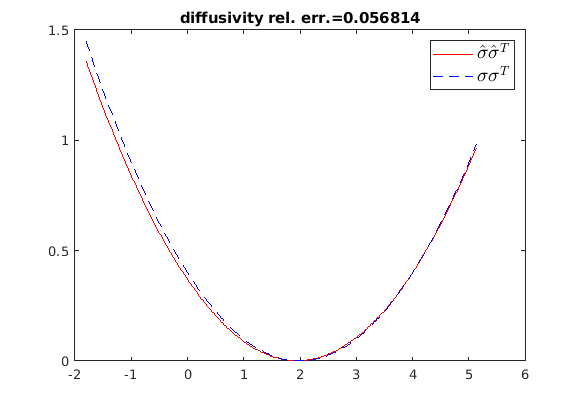

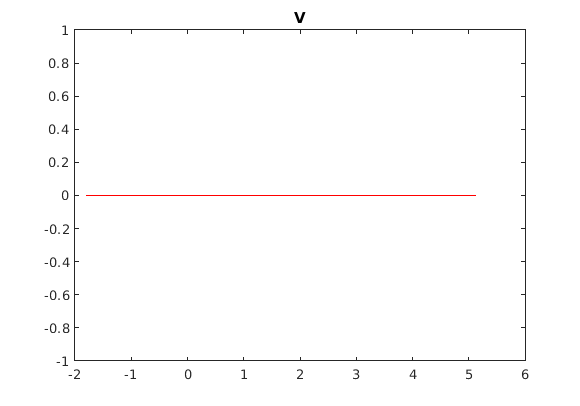

toggle_plot_drift = 1;
plot_driftdiff;

## Display interaction force

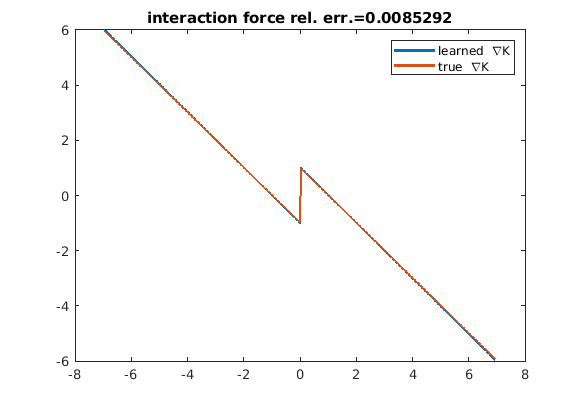

toggle_plot_IPforce = 1;
plot_K